# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Instru2\RawData_new'];    
Deci.SubjectList = 'gui';  
Deci.Step               =3; % Artifacts;
Deci.PCom               = 0;                           % Activates Parallel Computing (if availible)
Deci.Proceed =    0;     
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Instru2\ProcessedData_new'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};   
    Deci.DT.Locks      = [14 30 54];
    Deci.DT.Toi        = [-2 3]; 

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =1;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3];
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 


Deci.Analysis.Var = 0;
Deci.Analysis.Clean = 1;

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[23 31 51] [23 31 52] [23 32 51] [23 32 52]};
    
    %Deci.Plot.Lock = '2';
    %Deci.Plot.Conditions = {[23 31] [23 32]};
    Deci.Plot.GA = 0;

#### Math

Deci.Plot.Math.Form = {'[x2-x1]'};  
Deci.Plot.Math.Type = 0;

#### Time-Frequency

Deci.Plot.Freq.Foi = [3 inf];
Deci.Plot.Freq.Toi = [];
Deci.Plot.Freq.Channel = ['Reinhart-All'];
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxabs';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'


## **6. Run**

----------------------
Starting Artifactor


searching for artifacts in 62 channels
searching in trial 478 from 478



detected 47 artifacts
the call to "ft_artifact_zvalue" took 96 seconds


searching for artifacts in 4 channels
searching in trial 478 from 478



detected 66 artifacts
the call to "ft_artifact_zvalue" took 15 seconds
detected  47 muscle artifacts
detected  66 eog artifacts
rejected   40 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   13 trials with artifacts outside critical window
resulting 438 trials
the input is raw data with 62 channels and 478 trials


the call to "ft_redefinetrial" took 10 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 438 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 438 trials


showing a summary of the data for all channels and trials


computing metric [----|                                                    ]computing metric [--------/                                                ]computing metric [-------------                                            ]computing metric [----------------\                                        ]computing metric [--------------------|                                    ]computing metric [-------------------------/                               ]computing metric [------------------------------                           ]computing metric [----------------------------------\                      ]computing metric [--------------------------------------|                  ]computing metric [-------------------------------------------/             ]computing metric [-------------------------------------------------        ]computing metric [----------------------------------------------------\    ]computing metric [--------------------------------------------------------|]


422 trials marked as GOOD, 16 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 1, 2, 14, 27, 137, 143, 203, 275, 336, 354, 359, 394, 395, 398, 421, 427


the call to "ft_rejectvisual" took 58 seconds
the input is raw data with 62 channels and 422 trials


baseline correcting data 
scaling data with 1 over 55.754360
concatenating data......................................................................................................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 62x2072013
starting decomposition using runica

Input data size [20,2072013] = 20 channels, 2072013 frames/nAfter PCA dimension reduction,
  finding 20 ICA components using logistic ICA.
Decomposing 5180 frames per ICA weight ((400)^2 = 2072013 weights, Initial learning rate will be 0.001, block size 73.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange <

baseline correcting data 
scaling data with 1 over 105.205071
not concatenating data
starting decomposition using predetermined unmixing matrix
not applying the backprojection matrix to the sensor description
the call to "ft_componentanalysis" took 5 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


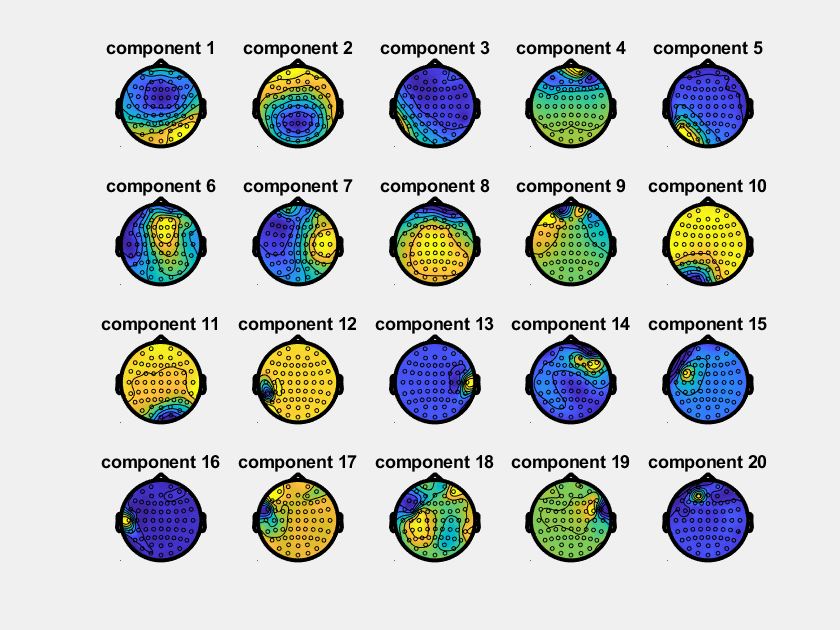

the call to "ft_topoplotIC" took 6 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 62 original channels
the input is raw data with 20 channels and 478 trials
detected   0 visual artifacts


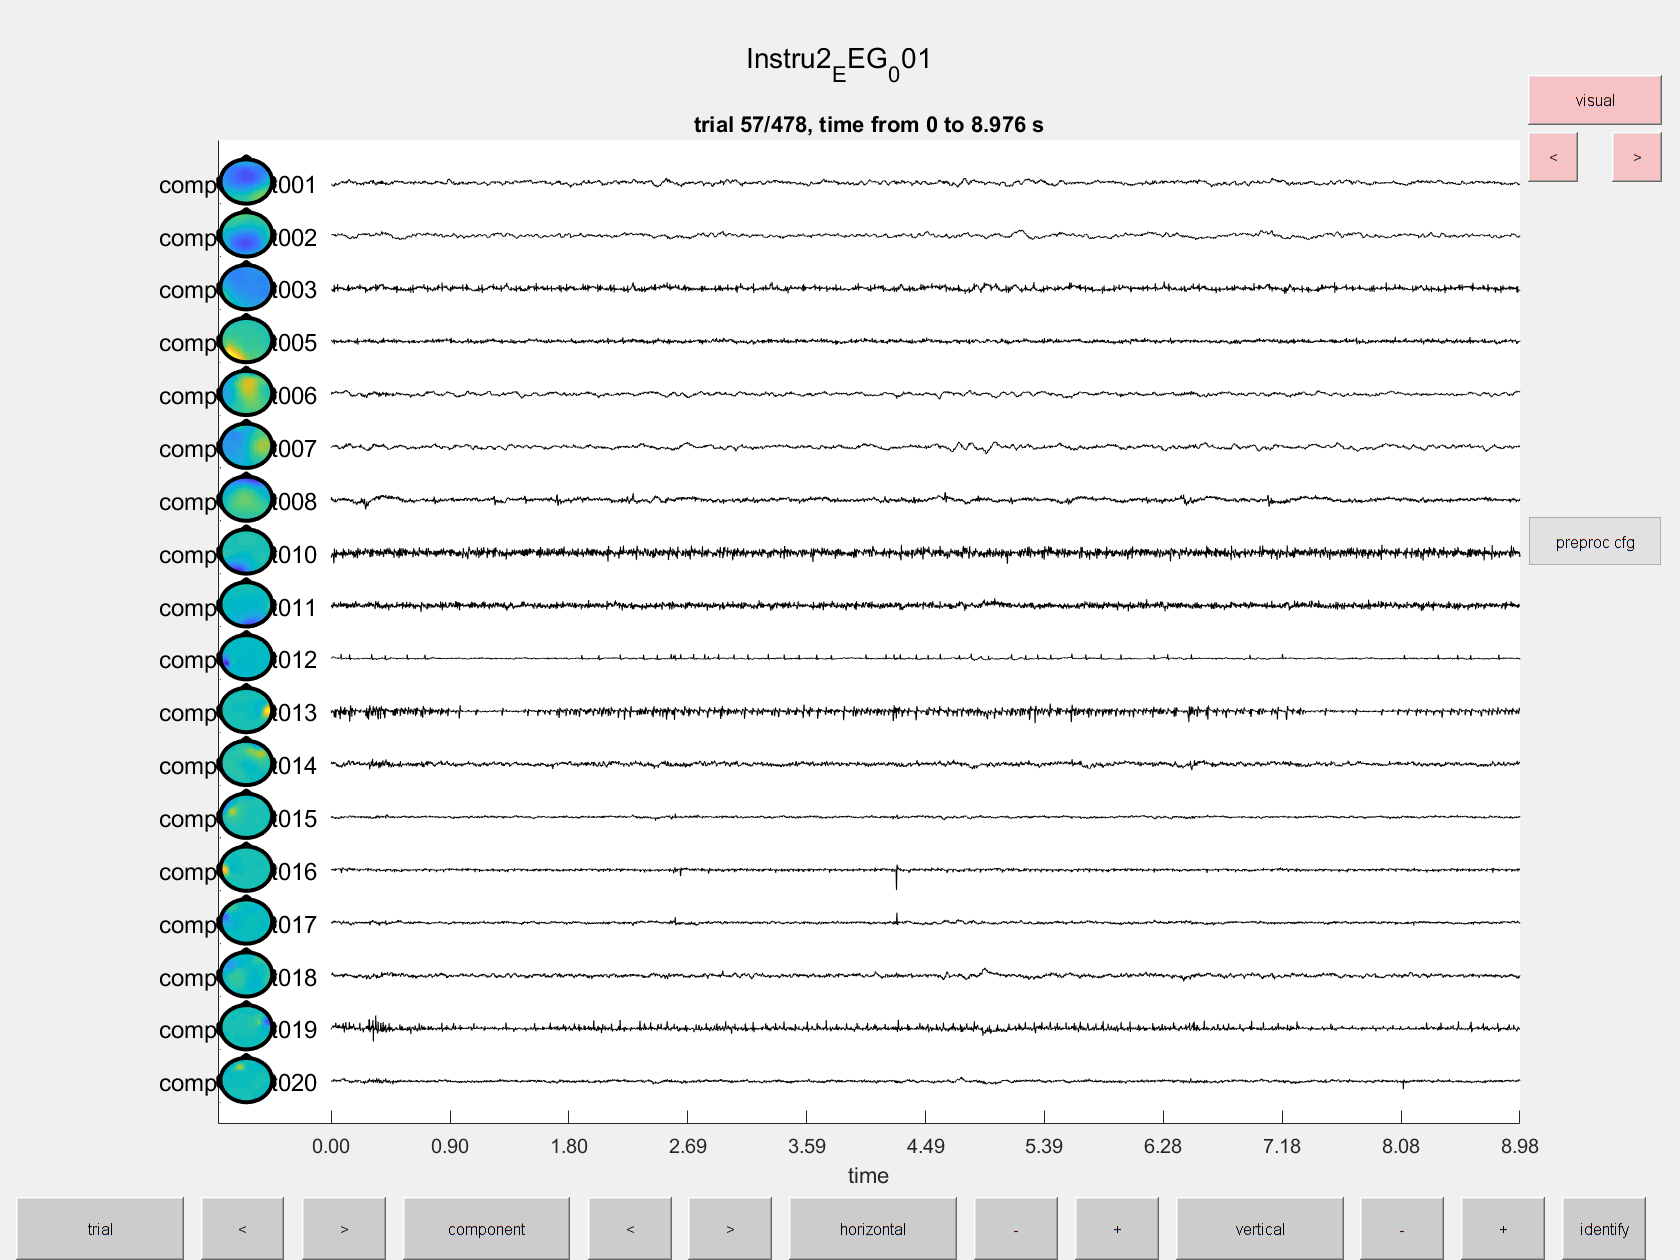

Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



Deci_Backend(Deci);